% AE6511 Hw5 Problem 4(b) MATLAB code
% Tomoki Koike 
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
clear all; close all; clc;



Iter     Func-count       f(x)      MeshSize     Method
    0           1        10.9499             1      
    1           2        7.57916             2     Successful Poll
    2           3        1.29039             4     Successful Poll
    3           5        1.29039             2     Refine Mesh
    4           7        1.29039             1     Refine Mesh
    5           9        1.29039           0.5     Refine Mesh
    6          10        0.20215             1     Successful Poll
    7          12        0.20215           0.5     Refine Mesh
    8          15        0.20215          0.25     Refine Mesh
    9          18        0.20215         0.125     Refine Mesh
   10          21       0.168371          0.25     Successful Poll
   11          24       0.168371         0.125     Refine Mesh
   12          28       0.168371        0.0625     Refine Mesh
   13          29      0.0171018         0.125     Successful Poll
   14          33      0.0171018        0.0625    

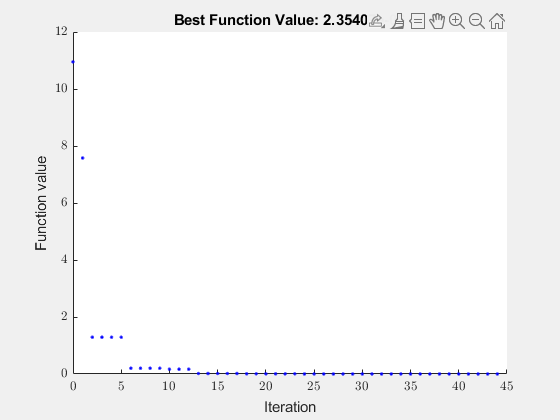

optsol =     1.4290    5.2360


fval = 2.3541e-06

lb = [0.001, 0];
ub = [10, 2*pi];
A = [];
b = [];
Aeq = [];
beq = [];
nonlcon = [];
x0 = [1, 2*pi-pi/3];
options = optimoptions('patternsearch','Display','iter', ...
    'PlotFcn',@psplotbestf);
[optsol,fval] = patternsearch(@objfcn,x0,A,b,Aeq,beq,lb,ub,nonlcon,options)

% Check 

tf = optsol(1);
tspan = linspace(0,tf,1000);
init_guess = [-20, 0, optsol(2)];
V = 15;

% ode45
optslv = optimset('TolX',1e-7,'TolFun',1e-7, ...
    'Display','off','MaxIter',500);
xout = ode45(@(t,x) ode(t,x,V),[0, tf], init_guess, optslv);
sol = xout.y'; T = xout.x;
x_sol = interp1(T,sol(:,1),tspan); 
y_sol = interp1(T,sol(:,2),tspan);
theta_sol = interp1(T,sol(:,3),tspan);
xdot_sol = V * cos(theta_sol) + 2;
ydot_sol = V * sin(theta_sol) - 6;

lambda1 = -cos(theta_sol)/(V+2*cos(theta_sol)-6*sin(theta_sol));
lambda2 = -sin(theta_sol)/(V+2*cos(theta_sol)-6*sin(theta_sol));

H = 1 + lambda1 .* xdot_sol + lambda2 .* ydot_sol;

% Shoreline
x_shore = linspace(min(x_sol),max(x_sol),1000);
y_shore = 0.002*x_shore.^3 + 0.25*x_shore - 25;

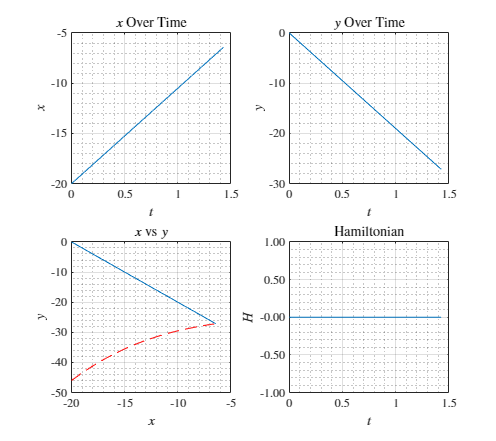

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x vs t
    subplot(2,2,1)
    plot(tspan, x_sol)
    title('$x$ Over Time')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on;
    % y vs t
    subplot(2,2,2)
    plot(tspan, y_sol)
    title('$y$ Over Time')
    xlabel('$t$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % x - y 
    subplot(2,2,3)
    plot(x_sol, y_sol)
    hold on;
    plot(x_shore,y_shore, '--r')
    title('$x$ vs $y$')
    xlabel('$x$')
    ylabel('$y$')
    grid on; grid minor; box on; hold off;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    ytickformat('%,.2f')
    grid on; grid minor; box on;
saveas(fig, 'p4b.png');

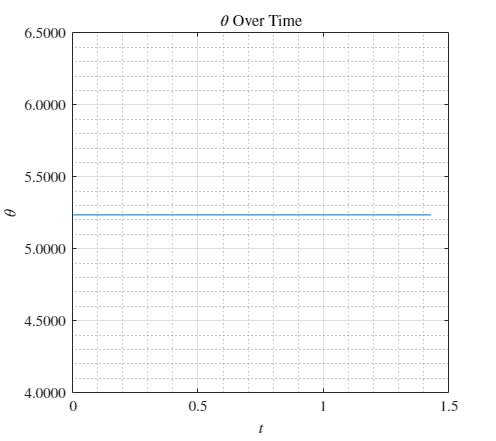

% Plot control 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, theta_sol)
    title('$\theta$ Over Time')
    xlabel('$t$')
    ylabel('$\theta$')
    ytickformat('%,.4f')
    grid on; grid minor; box on;
saveas(fig, 'p4b_theta.png');

function obj = objfcn(x)
    tf = x(1);
    tspan = linspace(0,tf,1000);
    init_guess = [-20, 0, x(2)];
    V = 15;

    % ode45
    optslv = optimset('TolX',1e-7,'TolFun',1e-7, ...
        'Display','off','MaxIter',500);
    xout = ode45(@(t,x) ode(t,x,V),[0, tf], init_guess, optslv);
    sol = xout.y'; T = xout.x;
    xsol = interp1(T,sol(:,1),tspan); ysol = interp1(T,sol(:,2),tspan);

    yshore = 0.002*xsol.^3 + 0.25*xsol - 25;

    obj = abs(ysol(end) - yshore(end));
end

function dxdt = ode(t,x,V)
    dxdt = zeros(3,1); 
    dxdt(1) = V * cos(x(3)) + 2; % x
    dxdt(2) = V * sin(x(3)) - 6; % y
    dxdt(3) = 0; % theta
end